clear

## Modern Controller test

load("params.mat", ...
    "sys_ss","inputs","outputs","states", "sigma");

sys_ss = ss(sys_ss.A, sys_ss.B,[1 0 0 0;0 0 1 0], 0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])

sys_ss =
 
  A = 
                      x    x_dot_c      theta  theta_dot
   x                  0          1          0          0
   x_dot_c            0        -10       1.65    -0.0134
   theta              0          0          0          1
   theta_dot          0     -55.81      64.02    -0.5198
 
  B = 
                  u
   x              0
   x_dot_c        2
   theta          0
   theta_dot  11.16
 
  C = 
                  x    x_dot_c      theta  theta_dot
   x_c            1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x_c    0
   theta  0
 
Continuous-time state-space model.



### Preparing the statespace model

C = ctrb(sys_ss)

C = 	1.0e+04 *

         0    0.0002   -0.0020    0.0221
    0.0002   -0.0020    0.0221   -0.2434
         0    0.0011   -0.0117    0.1900
    0.0011   -0.0117    0.1900   -2.0867


rank(C)

ans = 4

As the rank of the controllability matrix is full, a controller can be implemented.

firstly the poles of the openloop is found.

pole(sys_ss)

ans =          0
  -11.5752
   -6.3737
    7.4291


%pzmap(sys)

## State feedback control

pole assignment according to Controllable cannonical form, by place in matLab.

pole_placement = [-sigma*2+1i,-sigma*2-1i,-sigma*3+2i,-sigma*3-2i] % LQR could be used where Q=C'C and values for cost instead of the 1's

pole_placement =   -3.0667 + 1.0000i  -3.0667 - 1.0000i  -4.6000 + 2.0000i  -4.6000 - 2.0000i


F = place(sys_ss.A, sys_ss.B, pole_placement)

F =    -2.3881   -7.3003   14.5870    1.7392



A_cl = sys_ss.A-sys_ss.B*F

A_cl =          0    1.0000         0         0
    4.7761    4.6007  -27.5243   -3.4918
         0         0         0    1.0000
   26.6574   25.6783  -98.8147  -19.9340



 sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',[outputs(1),outputs(3)])

sys_cl =
 
  A = 
                      x    x_dot_c      theta  theta_dot
   x                  0          1          0          0
   x_dot_c        4.776      4.601     -27.52     -3.492
   theta              0          0          0          1
   theta_dot      26.66      25.68     -98.81     -19.93
 
  B = 
                  u
   x              0
   x_dot_c        2
   theta          0
   theta_dot  11.16
 
  C = 
                  x    x_dot_c      theta  theta_dot
   x_c            1          0          0          0
   theta          0          0          1          0
 
  D = 
          u
   x_c    0
   theta  0
 
Continuous-time state-space model.



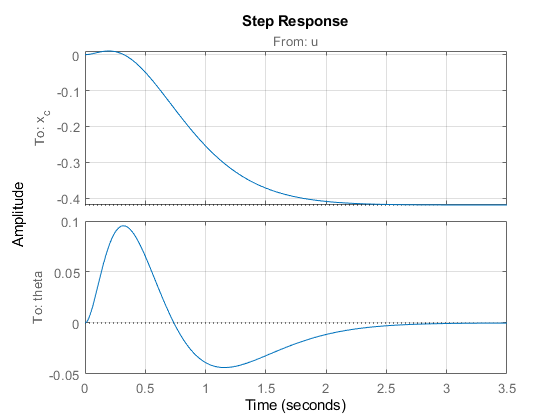

% sys_cl = ss(A_cl,sys_ss.B,sys_ss.C,0,'statename',states,'inputname',inputs,'outputname',outputs)
step(sys_cl)

stepinfo(sys_cl,'SettlingTimeThreshold',0.08)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


## PI state feedback

Making a integral control of the state feedback controller

A_e = [sys_ss.A zeros(4,2);
        sys_ss.C zeros(2,2)]

A_e =          0    1.0000         0         0         0         0
         0  -10.0000    1.6498   -0.0134         0         0
         0         0         0    1.0000         0         0
         0  -55.8140   64.0173   -0.5198         0         0
    1.0000         0         0         0         0         0
         0         0    1.0000         0         0         0


B_e = [sys_ss.B; zeros(2,1)]

B_e =          0
    2.0000
         0
   11.1628
         0
         0


C_e = [sys_ss.C zeros(2,2)]

C_e =      1     0     0     0     0     0
     0     0     1     0     0     0


D_e = 0

D_e = 0


sys_cl_e = ss(A_e, B_e, C_e, D_e);
rank_e = rank(ctrb(sys_cl_e))

rank_e = 5

## Observer

as the system is not full state, as only the cart position and pendulum angle is measured, an observer is needed

First the observability matrix is found from open loop

O = obsv(sys_ss.A, [1 0 0 0; 0 0 1 0])

O =     1.0000         0         0         0
         0         0    1.0000         0
         0    1.0000         0         0
         0         0         0    1.0000
         0  -10.0000    1.6498   -0.0134
         0  -55.8140   64.0173   -0.5198
         0  100.7476  -17.3551    1.7907
         0  587.1512 -125.3554   65.0351


rank(O)

ans = 4

finding eigs of A_cl

eig(A_cl)

ans =   -4.6000 + 2.0000i
  -4.6000 - 2.0000i
  -3.0667 + 1.0000i
  -3.0667 - 1.0000i



pole_obsv = [-2;-3;-4;-5] %[-4;-4.1;-4.2;-4.3]

pole_obsv =     -2
    -3
    -4
    -5


L = place(sys_ss.A', sys_ss.C', pole_obsv)'

L =     0.9294   -0.4477
   16.6466    4.4627
  -22.0320    2.5508
   78.4587   84.8033


implementing the loomenberger observer in A-matrix yields

Ace = [A_cl, sys_ss.B*F;zeros(size(sys_ss.A)), sys_ss.A-L*sys_ss.C]

Ace =          0    1.0000         0         0         0         0         0         0
    4.7761    4.6007  -27.5243   -3.4918   -4.7761  -14.6007   29.1741    3.4784
         0         0         0    1.0000         0         0         0         0
   26.6574   25.6783  -98.8147  -19.9340  -26.6574  -81.4923  162.8319   19.4142
         0         0         0         0   -0.9294    1.0000    0.4477         0
         0         0         0         0  -16.6466  -10.0000   -2.8129   -0.0134
         0         0         0         0   22.0320         0   -2.5508    1.0000
         0         0         0         0  -78.4587  -55.8140  -20.7860   -0.5198


Bce = [sys_ss.B;zeros(size(sys_ss.B))]

Bce =          0
    2.0000
         0
   11.1628
         0
         0
         0
         0


Cce = [sys_ss.C zeros(size(sys_ss.C))]

Cce =      1     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0


Dce = [0;0]

Dce =      0
     0


sys_cl = ss(Ace, Bce, Cce, Dce)

sys_cl =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1        0        1        0        0        0        0        0        0
   x2    4.776    4.601   -27.52   -3.492   -4.776    -14.6    29.17    3.478
   x3        0        0        0        1        0        0        0        0
   x4    26.66    25.68   -98.81   -19.93   -26.66   -81.49    162.8    19.41
   x5        0        0        0        0  -0.9294        1   0.4477        0
   x6        0        0        0        0   -16.65      -10   -2.813  -0.0134
   x7        0        0        0        0    22.03        0   -2.551        1
   x8        0        0        0        0   -78.46   -55.81   -20.79  -0.5198
 
  B = 
          u1
   x1      0
   x2      2
   x3      0
   x4  11.16
   x5      0
   x6      0
   x7      0
   x8      0
 
  C = 
       x1  x2  x3  x4  x5  x6  x7  x8
   y1   1   0   0   0   0   0   0   0
   y2   0   0   1   0   0   0   0   0
 
  D = 
       u1
   y1   0
  

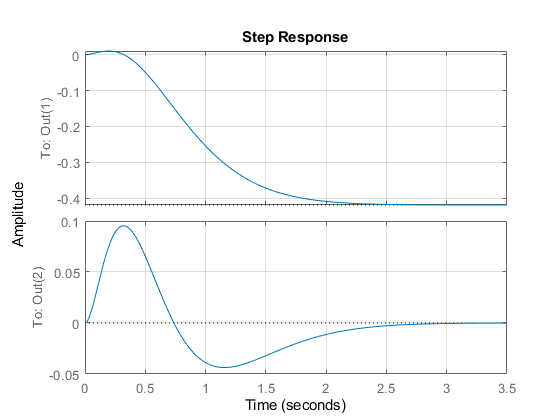


step(sys_cl)

stepinfo(sys_cl,'SettlingTimeThreshold',0.08)

ans = 2×1 struct array with fields:
    RiseTime
    SettlingTime
    SettlingMin
    SettlingMax
    Overshoot
    Undershoot
    Peak
    PeakTime


## Reference signal

Next step, add reference signal and calculate M and N matrix